clear all; clc;

load Sa1.mat;
Fs = 16000;
% sound(wavedata,Fs);
doc fdesign.lowpass.
d = fdesign.lowpass('Fp,Fst,Ap,Ast',100, 4800, 0.08, 58,Fs);

filt = design(d);

fvtool(filt);

filt

filt =      FilterStructure: 'Direct-Form FIR'                                                                                                                                  
          Arithmetic: 'double'                                                                                                                                           
           Numerator: [0.0157571417043324 0.072186227384665 0.166668860221311 0.244827866348546 0.244827866348546 0.166668860221311 0.072186227384665 0.0157571417043324]
    PersistentMemory: false                                                                                                                                              
                                                                                                                                                                         

filt.order

ans = 7


cost(filt)

ans = Number of Multipliers            : 8
Number of Adders                 : 7
Number of States                 : 7
Multiplications per Input Sample : 8
Additions per Input Sample       : 7

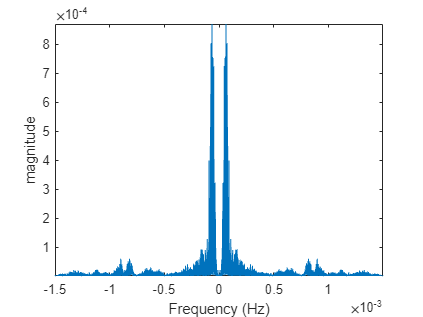



% filt(wavedata)

plotfft(wavedata,1/48*Fs,[-Fs/2000 Fs/2000]);

% 
x = lowpass(wavedata,5000,Fs)

x =    -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


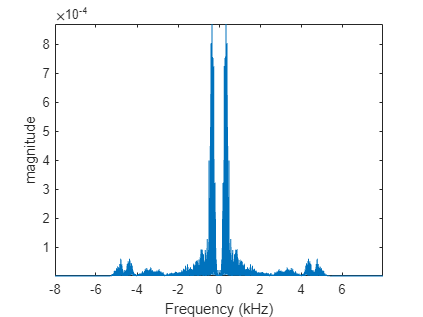


sound(x,Fs)

plotfft(x,1/Fs,[-9 9]);